result=zeros(1,91)

result =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x=zeros(1,91)

x =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


%left
for j=10:100
    dx=(3-0)/j;
    total=0;

    for i=1:j
        idk=(dx*i)+1;
        r=dx.*(sqrt(idk));
        total=total+(r);
    end
    result(j-9)=(total);
    x(j-9)=j;
    
end


result1=zeros(1,91)

result1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x1=zeros(1,91)

x1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


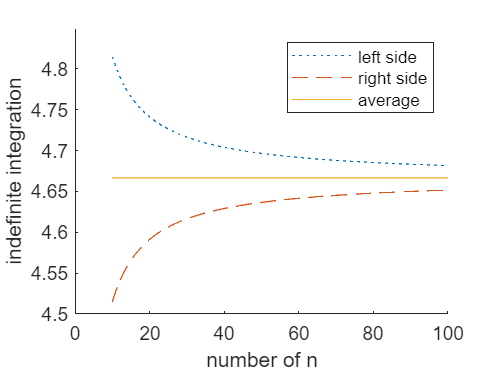

%right
for j=10:100
    dx=(3-0)/j;
    total=0;

    for i=1:j
        idk=(dx*(i-1))+1;
        r=dx.*(sqrt(idk));
        total=total+(r);
    end
    result1(j-9)=(total);
    x1(j-9)=j;
    
end



hold on
xlabel("number of n")
ylabel("indefinite integration")
plot(x,result,":")
plot(x1,result1, "--")
line1=zeros(1,91);
for i=1:91
    line1(i)=(result1(91)+result(91))/2;
end
plot(x1,line1)
legend("left side","right side", "average")
hold off